--- Dimensions: 2 ---


Function: F5


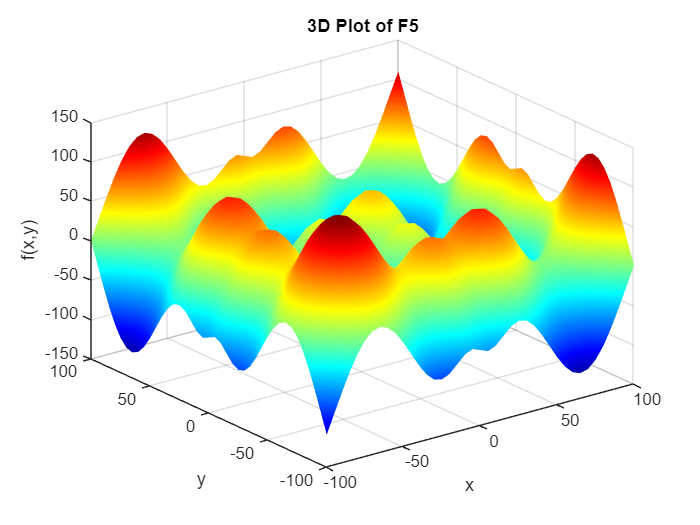

Algorithm: GA


  Avg Performance: -127.2700


  Std Deviation:   0.0000


  Best Performance: -127.2700


  Worst Performance: -127.2700


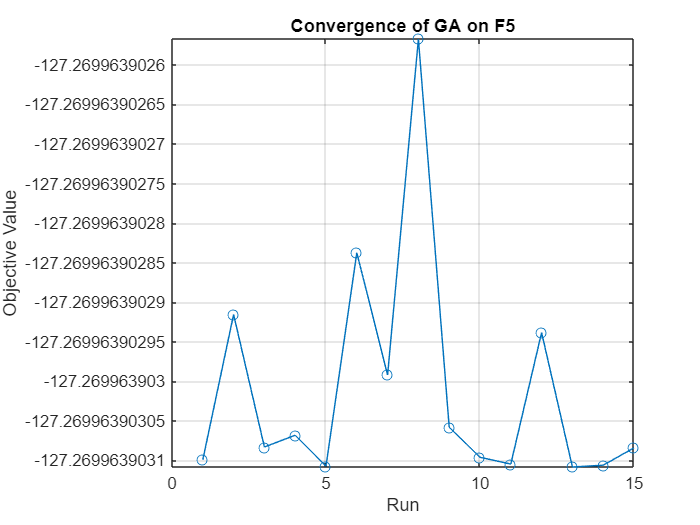

Algorithm: PSO


  Avg Performance: -126.6544


  Std Deviation:   2.3839


  Best Performance: -127.2700


  Worst Performance: -118.0371


Algorithm: SA


  Avg Performance: -107.8278


  Std Deviation:   20.4932


  Best Performance: -127.2693


  Worst Performance: -67.5257


Function: F7


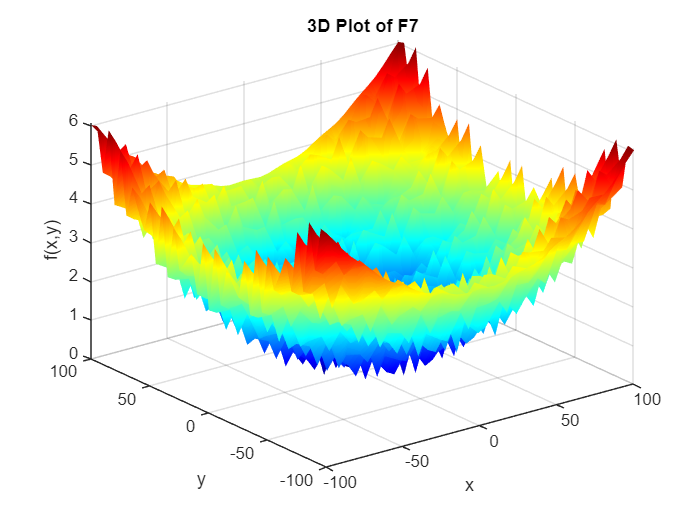

Algorithm: GA


  Avg Performance: 0.0539


  Std Deviation:   0.0592


  Best Performance: 0.0000


  Worst Performance: 0.1776


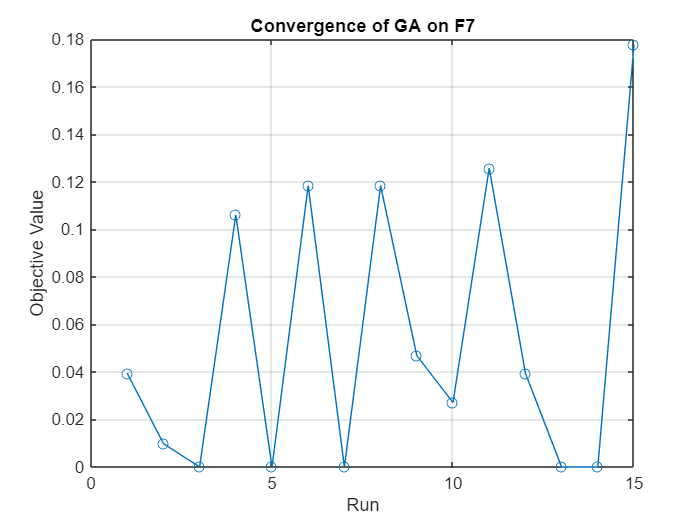

Algorithm: PSO


  Avg Performance: 0.0055


  Std Deviation:   0.0077


  Best Performance: 0.0000


  Worst Performance: 0.0299


Algorithm: SA


  Avg Performance: 0.0000


  Std Deviation:   0.0000


  Best Performance: 0.0000


  Worst Performance: 0.0000


Function: F13


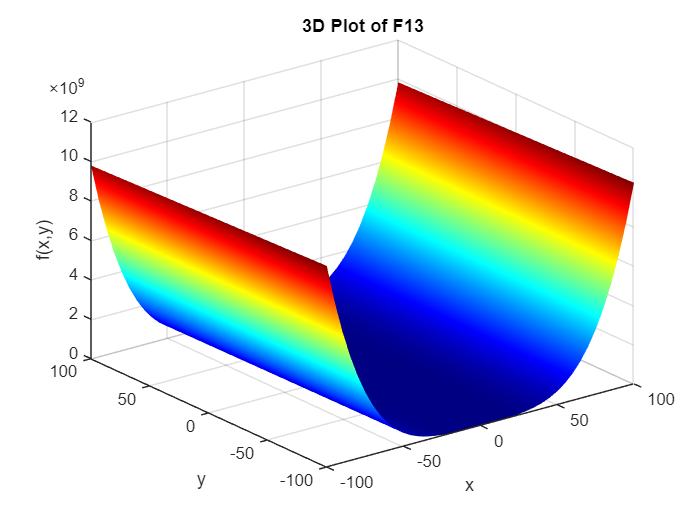

Algorithm: GA


  Avg Performance: 0.4305


  Std Deviation:   0.1322


  Best Performance: 0.3605


  Worst Performance: 0.8156


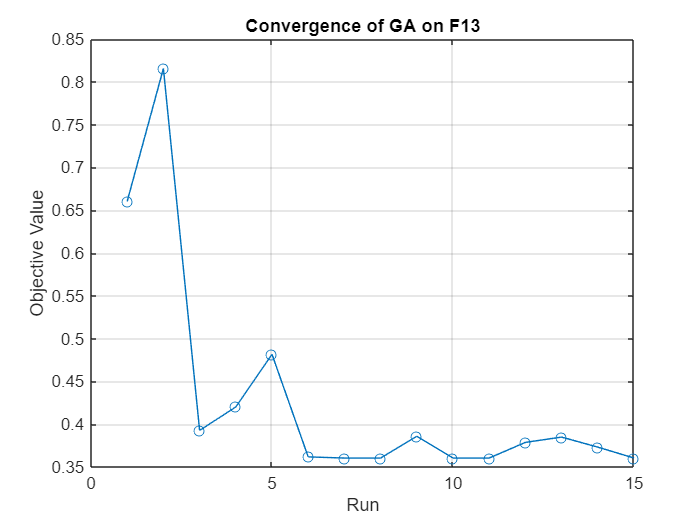

Algorithm: PSO


  Avg Performance: 0.4774


  Std Deviation:   0.4527


  Best Performance: 0.3605


  Worst Performance: 2.1138


Algorithm: SA


  Avg Performance: 0.4541


  Std Deviation:   0.1651


  Best Performance: 0.3605


  Worst Performance: 1.0000


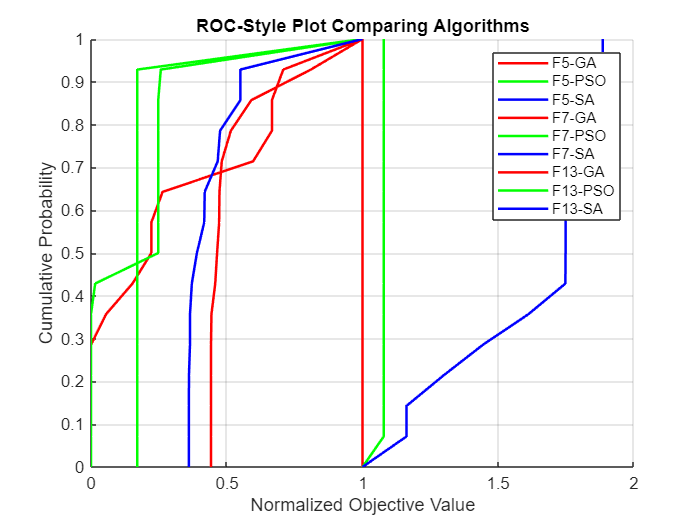

--- Dimensions: 10 ---


Function: F5


Algorithm: GA


  Avg Performance: -614.3640


  Std Deviation:   21.8589


  Best Performance: -636.3326


  Worst Performance: -566.7747


Algorithm: PSO


  Avg Performance: -570.4887


  Std Deviation:   13.9005


  Best Performance: -590.1855


  Worst Performance: -544.0211


Algorithm: SA


  Avg Performance: -366.9444


  Std Deviation:   96.0058


  Best Performance: -554.0675


  Worst Performance: -205.5595


Function: F7


Algorithm: GA


  Avg Performance: 0.0077


  Std Deviation:   0.0200


  Best Performance: 0.0000


  Worst Performance: 0.0699


Algorithm: PSO


  Avg Performance: 0.1491


  Std Deviation:   0.2036


  Best Performance: 0.0000


  Worst Performance: 0.8133


Algorithm: SA


  Avg Performance: 0.0000


  Std Deviation:   0.0000


  Best Performance: 0.0000


  Worst Performance: 0.0000


Function: F13


Algorithm: GA


  Avg Performance: 12.8224


  Std Deviation:   21.6175


  Best Performance: 0.9454


  Worst Performance: 66.0636


Algorithm: PSO


  Avg Performance: 325.4513


  Std Deviation:   873.5278


  Best Performance: 1.5390


  Worst Performance: 3172.9137


Algorithm: SA


  Avg Performance: 8.8962


  Std Deviation:   0.0324


  Best Performance: 8.8351


  Worst Performance: 8.9384


% --- Main Script ---
clear; clc;

% Define dimensions
dimensions = [2, 10]; % Add D=100 if desired

% Number of runs for each optimization algorithm
numRuns = 15;

% Define functions from CEC'2005 suite
functions = {@F5, @F7, @F13};
functionNames = {'F5', 'F7', 'F13'};

% Define optimization algorithms
algorithms = {'GA', 'PSO', 'SA'};

% Genetic Algorithm options
gaOptions = optimoptions('ga', 'Display', 'off', 'PopulationSize', 50, 'MaxGenerations', 100);

% Particle Swarm Optimization options
psoOptions = optimoptions('particleswarm', 'Display', 'off', 'SwarmSize', 50, 'MaxIterations', 100);

% Simulated Annealing options
saOptions = optimoptions('simulannealbnd', 'Display', 'off', 'MaxIterations', 300);

% Store results for ROC-style plots
rocData = struct();

% Loop over dimensions
for d = dimensions
    fprintf('--- Dimensions: %d ---\n', d);
    
    % Loop over functions
    for fIndex = 1:length(functions)
        func = functions{fIndex};
        funcName = functionNames{fIndex};
        fprintf('Function: %s\n', funcName);
        
        % Define search space bounds
        lb = -100 * ones(1, d); % Lower bound
        ub = 100 * ones(1, d);  % Upper bound

        % Ensure bounds are of type double
        lb = double(lb);
        ub = double(ub);

        % Plot the function in 3D (only for D=2)
        if d == 2
            figure;
            [x, y] = meshgrid(-100:5:100, -100:5:100);
            z = arrayfun(@(a, b) func([a, b]), x, y);
            surf(x, y, z);
            title(['3D Plot of ', funcName]);
            xlabel('x'); ylabel('y'); zlabel('f(x,y)');
            colormap jet; shading interp;
        end

        % Loop over algorithms
        for aIndex = 1:length(algorithms)
            algorithm = algorithms{aIndex};
            fprintf('Algorithm: %s\n', algorithm);
            
            results = zeros(1, numRuns);
            
            % Run optimization multiple times
            for run = 1:numRuns
                switch algorithm
                    case 'GA'
                        [~, fval] = ga(func, d, [], [], [], [], lb, ub, [], gaOptions);
                        results(run) = fval;
                    case 'PSO'
                        [~, fval] = particleswarm(func, d, lb, ub, psoOptions);
                        results(run) = fval;
                    case 'SA'
                        % Define a starting point within the bounds
                        x0 = (lb + ub) / 2; 
                        [~, fval] = simulannealbnd(func, x0, lb, ub, saOptions);
                        results(run) = fval;
                end
            end
            
            % Calculate statistics
            avgPerformance = mean(results);
            stdDeviation = std(results);
            bestPerformance = min(results);
            worstPerformance = max(results);
            
            % Store data for ROC-style plots (normalized performance)
            rocData.(funcName).(algorithm) = results / max(results);

            % Display results
            fprintf('  Avg Performance: %.4f\n', avgPerformance);
            fprintf('  Std Deviation:   %.4f\n', stdDeviation);
            fprintf('  Best Performance: %.4f\n', bestPerformance);
            fprintf('  Worst Performance: %.4f\n', worstPerformance);

            % Plot convergence (only for D=2)
            if d == 2 && strcmp(algorithm, 'GA')
                figure;
                plot(1:numRuns, results, '-o');
                title(['Convergence of ', algorithm, ' on ', funcName]);
                xlabel('Run'); ylabel('Objective Value');
                grid on;
            end
        end
    end
    
    % Generate ROC-style plots (only for D=2)
    if d == 2
        figure;
        hold on;
        colors = {'r', 'g', 'b'};
        legendEntries = {};
        
        for fIndex = 1:length(functions)
            funcName = functionNames{fIndex};
            
            for aIndex = 1:length(algorithms)
                algorithm = algorithms{aIndex};
                dataROC = rocData.(funcName).(algorithm); % Normalized data
                
                % Sort data to create an ROC-like curve
                sortedDataROC = sort(dataROC);
                plot(sortedDataROC, linspace(0, 1, numRuns), colors{aIndex}, 'LineWidth', 1.5);
                
                legendEntries{end+1} = [funcName, '-', algorithm];
            end
        end
        
        title('ROC-Style Plot Comparing Algorithms');
        xlabel('Normalized Objective Value');
        ylabel('Cumulative Probability');
        legend(legendEntries);
        grid on;
    end
end


% --- End of Main Script ---

% --- Benchmark Functions ---
function y = F5(x)
    % Schwefel’s Problem (Example Placeholder)
    y = sum(-x .* sin(sqrt(abs(x)))); % Replace with actual CEC'2005 definition
end

function y = F7(x)
    % Griewank’s Function (Example Placeholder)
    y = sum(x.^2) / 4000 - prod(cos(x ./ sqrt(1:length(x)))) + 1; % Replace with actual CEC'2005 definition
end

function y = F13(x)
    % Expanded Griewank’s plus Rosenbrock’s Function (Example Placeholder)
    yRosenbrockPart = sum(100 * (x(2:end) - x(1:end-1).^2).^2 + (x(1:end-1) - 1).^2); 
    yGriewankPart = sum(x.^2) / 4000 - prod(cos(x ./ sqrt(1:length(x)))) + 1;
    y = yRosenbrockPart + yGriewankPart; % Replace with actual CEC'2005 definition
end

% --- End of Benchmark Functions ---
